# SAMEKO - LCC for switches and crossings

WP with Kristofer & Arne

## Input

clear global
clear all
clc

% read regression results
[prev,korr,fail,renewal,MGT,nb_freight_year,nb_pass_year,delay_min,MGT_lifetime,headers,~] = read_input_data();
switches = [1 2 3 4 7];
prev = prev(:,switches);
korr = korr(:,switches);
fail = fail(:,switches);
renewal = renewal(1);
nb_freight_year = nb_freight_year(switches);
nb_pass_year = nb_pass_year(switches);
delay_min = delay_min(switches);
korr_main_cost = 8000; % sek per activity, 2014-price level
prev_main_cost = 5000; % sek per activity, 2014-price level
%components = 16:23;
headers = headers(switches);
% set parameters
time_horizon_switches_max = 75;%max(year_lifetime(:));
% plot all inputs
data = {prev, korr, fail, headers};
%plot_figure("input", data);

## LCC

% LCC for the time_horizon_switches
data_lcc = {prev,korr,fail,nb_freight_year,nb_pass_year,delay_min,time_horizon_switches_max,switches,korr_main_cost,prev_main_cost};
[dir_maint,prev_cap,korr_cap,disr] = assess_lcc(data_lcc);
% plot the yearly undiscounted costs
data = {dir_maint, prev_cap, korr_cap, disr, renewal, headers};
%plot_figure("yearly undiscounted",data);
% annuity
[ann,tpv] = get_ann_tpv(dir_maint, prev_cap, korr_cap, disr, renewal)

ann = 	1.0e+05 *

    3.9229    4.3278    3.7162    3.9361    3.9093


tpv = 	1.0e+07 *

    1.0359    1.1428    0.9813    1.0394    1.0323


## Annuity and optimal lifetime

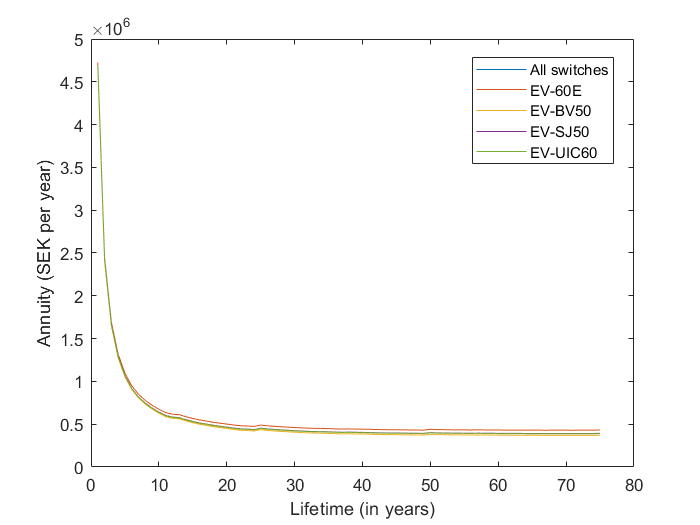

% Find the optimal lifetime (where annuity is minimal)
[optimal_lifetime_switches, min_annuity_switches, annuity_switches] = get_optimal(data_lcc, time_horizon_switches_max, headers, renewal);
% Annuity for switches
plot(1:time_horizon_switches_max, annuity_switches)
legend(headers, "Location","best")
xlabel("Lifetime (in years)")
ylabel("Annuity (SEK per year)")

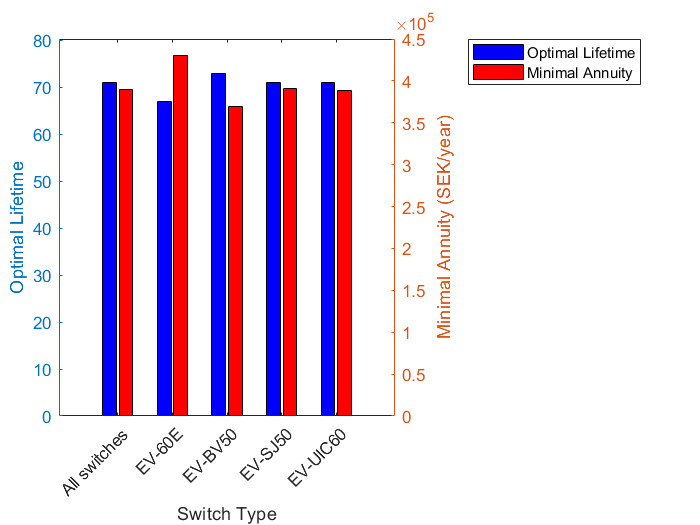

% optimal lifetime
data_figure = {switches, optimal_lifetime_switches, min_annuity_switches, headers};
plot_figure("optimal-lifetime", data_figure);

## Sensitivity analyses

### > Maintenance costs

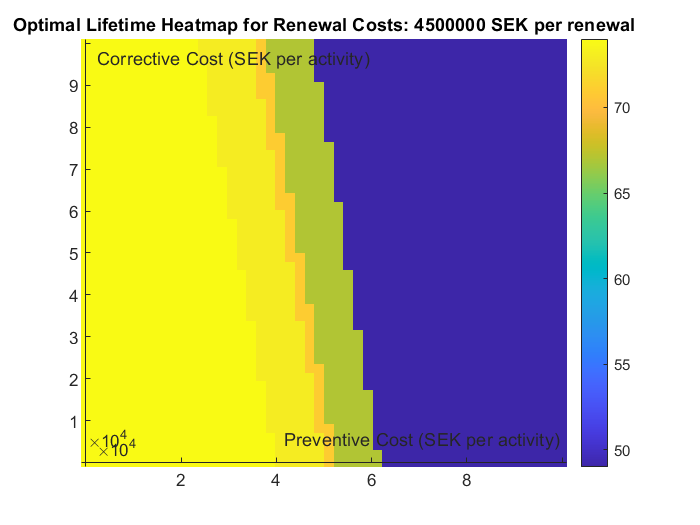

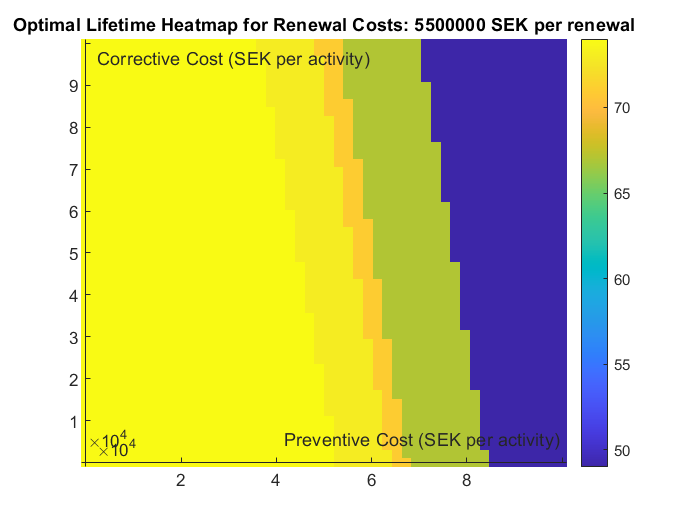

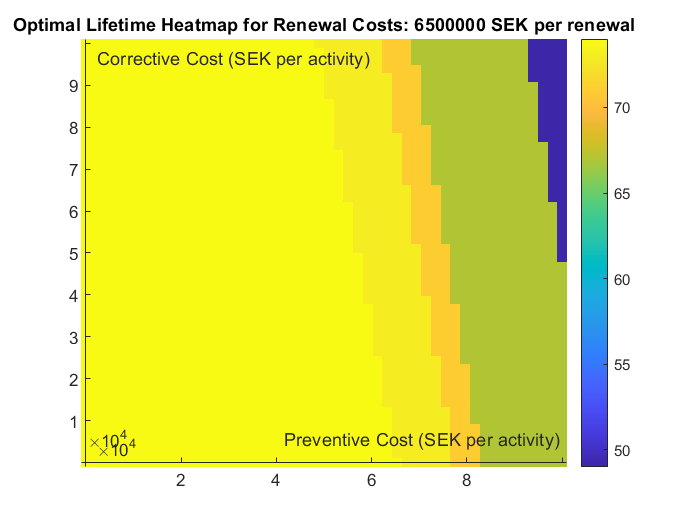

main_cost = linspace(0,100000,50); % in SEK per activity
renewal_costs = [4.5 5.5 6.5]*10^6; % in SEK per renewal
switch_nb = 1;
opt_lifetime = zeros(length(main_cost), length(main_cost), 3);
for i=1:3
    for korr_c=1:length(main_cost)
        for prev_c=1:length(main_cost)
            data_lcc = {prev(:,switch_nb),korr(:,switch_nb),fail(:,switch_nb),nb_freight_year(switch_nb),nb_pass_year(switch_nb),...
                delay_min(switch_nb),time_horizon_switches_max,switches(switch_nb),main_cost(korr_c),main_cost(prev_c)};
            [opt_lifetime(korr_c,prev_c,i),~,~] = get_optimal(data_lcc, time_horizon_switches_max, headers(switch_nb), renewal_costs(i));
        end
    end
end

% Plot heat map of opt_lifetime for each value of renewal costs
for i = 1:3
    figure;
    imagesc(main_cost, main_cost, opt_lifetime(:,:,i));
    colorbar;
    xlabel('Preventive Cost (SEK per activity)');
    ylabel('Corrective Cost (SEK per activity)');
    title(['Optimal Lifetime Heatmap for Renewal Costs: ' num2str(renewal_costs(i)) ' SEK per renewal']);
    
    % Set the axes to start from 0 at the bottom-left corner
    set(gca, 'YDir', 'normal', 'XAxisLocation', 'origin', 'YAxisLocation', 'origin');
end